# Conditional mutual information between successive letters in written English

In this extension activity, we will continue our analysis of written English extracted from the [Seinfeld](https://en.wikipedia.org/wiki/Seinfeld) scripts as begun in the previous module.

# Preparing your environment

As per [entropyOfCharacters.mlx](matlab:open('./entropyOfCharacters.mlx')), you may need to add your entropy scripts to the path for Matlab, e.g. using `addpath('../EntropyScripts/');` where you supply the path to your entropy scripts or the completed ones; i.e. you may need to change the folder referenced below:

pathToEntropyScripts = '../../Module01-Entropy/MatlabSimpleFunctions/completed';
addpath(pathToEntropyScripts);

# Conditional mutual information between successive letters in written English

1. Download the data from the links on Module 2, load into Matlab and preprocess as per steps 1-4 of the activity [entropyOfCharacters.mlx](matlab:open('./entropyOfCharacters.mlx')) from Module 2, such that we have the characters stored in the array `processedStr:`

*Note:* you may need to alter the filename/path to match your own --

str = fileread('./Seinfeld-scripts-textOnly.txt');
processedStr = regexprep(str, '[!"#$%&''()\*,-./;<=>?\[\\\]_`{}~]', ''); % Remove punctuation characters
processedStr = regexprep(processedStr, '[0-9]', ''); % Removed digits
processedStr = replace(processedStr, newline, ' '); % Replace newline characters with spaces
processedStr = lower(processedStr); % Convert all upper case into lower case
unique(processedStr)

ans = ' abcdefghijklmnopqrstuvwxyz'

2. We previously computed the mutual information between characters over several lags between these characters. In particular, we examined the mutual information between characters separated by a lag of 2, and posed the question of whether the information carried by the earlier character about the later one is also included in the character in between them. Think about how you could investigate this question using conditional mutual information?

3. Calculate the mutual information between characters separated by another character, conditioned on the character in the middle. Use our function `conditionalmutualinformationempirical()`.

*Hint*: You should create vectors of samples for each of: the earlier character, the middle character, and the later character; and pass these through to the function. Recall that to select all but the last two items in an array `x`, you can refer to `x(1:end-2)`, and similarly to select all but the first and last items in an array you can refer to `x(2:end-1)`.

% Compute the mutual information between successive characters conditioned on the character in between:
conditionalmutualinformationempirical(processedStr(1:end-2), processedStr(3:end), processedStr(2:end-1))

ans = 0.7391

4. Compare this conditional mutual information to the mutual information between the two characters separated by another character as computed in the previous module (see the result for a lag of 2 on the sample plot in that activity). Is the conditional mutual information here larger or smaller than that? What does this tell us about the structure of the relationships in sequences of characters in English text?

5. *Challenge*: Can you compute such conditional mutual information over lags of up to 5 characters, conditioning on all intervening characters, and then plot these? Alternatively, you could compute the joint mutual information from sets of consecutive characters (up to 5 of them) to the next character. (How are these two quantities related?).

*Note* that the calculations here will take longer than previous ones since we are dealing with higher and higher order multivariate spaces (this is why we optimised the entropy code when first processing this data set). What is the size of the probability space we are estimating once we are looking at a lag of 5 (i.e. 4 characters in between the previous and next)? Do you think we can properly estimate the joint probabilities here from the amount of data that we have?

% Compute the mutual information between successive characters conditioned on up to 5 characters in between:
maxLag = 5;

condMisVsLag = zeros(1, maxLag);
conditionalCharacters = [];

nextChar = processedStr(maxLag+1:end);
for lag=1:maxLag
    sourceChar = processedStr(maxLag+1-lag:end-lag);
    if (lag == 1)
        % Nothing to condition on, just compute MI
        condMisVsLag(lag) = mutualinformationempirical(sourceChar, nextChar);
    else
        condMisVsLag(lag) = conditionalmutualinformationempirical(sourceChar, nextChar, conditionalCharacters);
    end
    fprintf('cond MI over lag %d is %.4f\n', lag, condMisVsLag(lag));
    conditionalCharacters = [conditionalCharacters, sourceChar'];
end

cond MI over lag 1 is 0.7196
cond MI over lag 2 is 0.7391
cond MI over lag 3 is 0.5251
cond MI over lag 4 is 0.3197
cond MI over lag 5 is 0.2474


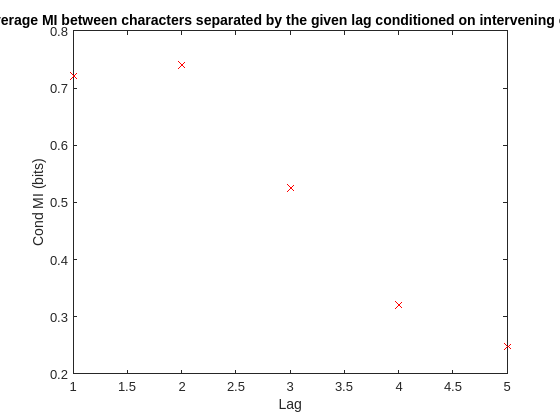


figure();
plot(1:maxLag, condMisVsLag, 'rx');
xlabel('Lag')
ylabel('Cond MI (bits)');
title('Average MI between characters separated by the given lag conditioned on intervening chars');